clear

importOptions = spreadsheetImportOptions();

importOptions.Sheet = "Tableaux2et3et4";
importOptions.VariableNames = ["Unit", "Node", "Fuel", "Pmin", "Pmax", "Rpos", "Rneg", "RU", "RD", "UT", "DT", "C", "CRpos", "CRneg", "Csu", "Pini", "Uini", "Tini"];
importOptions.VariableTypes = ["double", "double", "categorical", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];
importOptions.DataRange = "A3:R14";

dataC = readtable('Donnees_Projet_Optimisation.xlsx', importOptions);

importOptions = spreadsheetImportOptions();
importOptions.Sheet = "Tableau1";
importOptions.VariableNames = ["H", "D"];
importOptions.VariableTypes = ["double", "double"];
importOptions.DataRange = "A2:B25";

dataD = readtable('Donnees_Projet_Optimisation.xlsx', importOptions);
clear importOptions

% Standardisation des données
% min --> h
dataC.RU = dataC.RU*60;
dataC.RD = dataC.RD*60;

% Données
h = length(dataD.H);
c = length(dataC.Unit);
n = c*h;
partR = 0.05;  % Niveau de sécurité pour la réserve (pourcentage de la demande)


% Fonction obj
% P : 24*12*2 paramètres
% P : [C1(1), C1(2), ..., C1(h), C2(1), ..., C2(n), ..., Cc(n)   ,   i1(1), ... , ic(n)]
%    C : Puissance
%    i : var entière
intcon = n+1:3*n;
f_obj = @(P) sum(reshape(P(1:n), 24, 12)*dataC.C) + penalityInt(P, intcon);   % Penalité : var entière

f_lin = [reshape((dataC.C*ones(1, h))', 1, n), zeros(1, n), reshape((dataC.Csu*ones(1, h))', 1, n)];

% Contrainte égalités
% Demande
D_eq = repmat(-eye(h), 1, c);
bD_eq = -dataD.D;

Aeq = [D_eq, zeros(h, 2*n)];
beq = bD_eq;

% Limitation variation puissance : 

RU_ineq = eye(n);
bRU_ineq = reshape((dataC.RU*ones(1, h))', n, 1);
diago = zeros(1, n-1);
for i=0:c-1
    diago(i*h+1:(i+1)*h-1) = -ones(1, h-1);
    bRU_ineq(i*h+1) = bRU_ineq(i*h+1) + dataC.Pini(i+1);
end
RU_ineq = [RU_ineq + diag(diago, -1), zeros(n)];


RD_ineq = -eye(n);
bRD_ineq = reshape((dataC.RD*ones(1, h))', n, 1);
diago = zeros(1, n-1);
for i=0:c-1
    diago(i*h+1:(i+1)*h-1) = ones(1, h-1);
    bRD_ineq(i*h+1) = bRD_ineq(i*h+1) - dataC.Pini(i+1);
end
RD_ineq = [RD_ineq + diag(diago, -1), zeros(n)];

% Réponse à la demande  : somme(Ci(k)) > D(k)
D_ineq = [repmat(-eye(h), 1, c), zeros(h, n)];
bD_ineq = -dataD.D;

% Réponse à la demande  : somme(Ci(k)) < D(k)
D_ineq = [D_ineq ; repmat(eye(h), 1, c), zeros(h, n)];
bD_ineq = [bD_ineq ; dataD.D+10];

% On/off :
% Pmin(i)*ii(k) - Ci(k) < 0
Pmin_ineq = [-eye(n), diag(reshape((dataC.Pmin*ones(1, h))',n, 1))];   % Explication : (dataC.Pmin*ones(1, h))' : [Pmin(1) ... Pmin(1);Pmin(2) ... Pmin(2) ; .. ; Pmin(c) ... Pmin(c)]
bmin_ineq = zeros(n, 1);

% Ci(k) - Pmax(i)*ii(k) < 0.1
Pmax_ineq = [eye(n), -diag(reshape((dataC.Pmax*ones(1, h))',n, 1))];
bmax_ineq = 0.1*ones(n, 1);

% Matrices finales Puiss et état
Aineq_2n = [RU_ineq ; RD_ineq ; Pmin_ineq ; Pmax_ineq];
bineq_2n = [bRU_ineq ; bRD_ineq ; bmin_ineq ; bmax_ineq];
%Aineq = [Aineq ; Dineq];
%bineq = [bineq ; bD_ineq];

% Variable de démarage
Dem_ineq = eye(n);
bDem_ineq = zeros(n, 1);
diago = zeros(1, n-1);
for i=0:c-1
    diago(i*h+1:(i+1)*h-1) = -ones(1, h-1);
    bDem_ineq(i*h+1) = dataC.Uini(i+1);
end
Dem_ineq = [Dem_ineq + diag(diago, -1), -eye(n)];


Dem1_ineq = -eye(n);
bDem1_ineq = ones(n, 1);
diago = zeros(1, n-1);
for i=0:c-1
    diago(i*h+1:(i+1)*h-1) = ones(1, h-1);
    bDem1_ineq(i*h+1) = 1 - dataC.Uini(i+1);
end
Dem1_ineq = [Dem1_ineq + diag(diago, -1), 2*eye(n)];

Dem_ineq = [Dem_ineq ; Dem1_ineq];
bDem_ineq = [bDem_ineq ; bDem1_ineq];


% Matrice inégalités
Aineq = [Aineq_2n, zeros(4*n, n);
    zeros(2*n, n), Dem_ineq];
bineq = [bineq_2n ; bDem_ineq];


% Bornes
lb = zeros(3*n, 1);
ub = [reshape((dataC.Pmax*ones(1, h))', n, 1); ones(2*n, 1)];

% Initialisatoin
P0 = reshape((dataC.Pmin+dataC.Pmax)/2*ones(1, h), n, 1);


% Options
opt_ga = optimoptions("ga", 'CrossoverFcn', {@Crossover_maison, n}, 'CrossoverFraction', 0.5, 'MaxGenerations', 4, 'PlotFcn',"gaplotdistance");
opt_lin = optimoptions("intlinprog");


% Appel ga
% [xsol, fval] = ga(f_obj, 2*n, Aineq, bineq, [], [], lb, ub, '', opt_ga)

% Appel intlinprog
useGlobal = false;
%x0 = [Pmin*ones(1, n), ones(1, n), zeros(1, n)];
if useGlobal
    nbPoints=10;
    X = GenerateInitialPoint(nbPoints, Aineq, bineq, Aeq, beq, lb, ub);
    for xi=X
        [xsol, fval] = intlinprog(f_lin, intcon, Aineq, bineq, Aeq, beq, lb, ub, xi, opt_lin)
    end
else
    [xsol, fval] = intlinprog(f_lin, intcon, Aineq, bineq, Aeq, beq, lb, ub, opt_lin)
end

LP:                Optimal objective value is 428688.182945.                                        

Cut Generation:    Applied 46 implication cuts, 1 cover cut,                                        
                   15 mir cuts, 2 Gomory cuts,                                                      
                   and 3 clique cuts.                                                               
                   Lower bound is 429324.924934.                                                    

Heuristics:        Found 1 solution using rounding.                                                 
                   Upper bound is 429325.809250.                                                    
                   Relative gap is 0.00%.                                                          


Optimal solution found.

Intlinprog stopped at the root node because the objective value is within a gap tolerance o

xsol =    30.4000
   30.4000
   30.4000
   30.4000
   30.4000
   30.4000
   30.4000
  150.4000
  152.0000
  152.0000


fval = 4.2933e+05

Psol = reshape(xsol(1:n).*xsol(n+1:2*n), 24, 12)

Psol =    30.4000   30.4000         0         0         0   54.2500  155.0000  400.0000  400.0000  300.0000  265.7850  140.0000
   30.4000   30.4000         0         0         0  105.5150  155.0000  400.0000  400.0000  300.0000  108.5000  140.0000
   30.4000   30.4000         0         0         0   54.2500  126.7500  400.0000  400.0000  300.0000  108.5000  140.0000
   30.4000   30.4000         0         0         0   54.2500   54.2500  400.0000  400.0000  300.0000  154.4950  140.0000
   30.4000   30.4000         0         0         0   54.2500   54.2500  400.0000  400.0000  300.0000  154.4950  140.0000
   30.4000   30.4000         0         0         0   54.2500  105.2500  400.0000  400.0000  300.0000  130.0000  140.0000
   30.4000   30.4000         0         0         0  155.0000  155.0000  400.0000  400.0000  300.0000  310.0000  180.5700
  150.4000   59.0300         0         0         0  155.0000  155.0000  400.0000  400.0000  300.0000  310.0000  350.0000
  152.0000  152.0000  143

dataC.C

ans =    13.3200
   13.3200
   20.7000
   20.9300
   26.1100
   10.5200
   10.5200
    6.0200
    5.4700
         0


% Contrainte RU
RU_ineq*xsol(1:2*n)-bRU_ineq

ans =  -165.6000
 -120.0000
 -120.0000
 -120.0000
 -120.0000
 -120.0000
 -120.0000
    0.0000
 -118.4000
 -120.0000


% Contrainte RD
RD_ineq*xsol(1:2*n)-bRD_ineq

ans =   -74.4000
 -120.0000
 -120.0000
 -120.0000
 -120.0000
 -120.0000
 -120.0000
 -240.0000
 -121.6000
 -120.0000


% Contrainte Demande
D_eq*xsol(1:n) - bD_eq

ans = 	1.0e+-12 *

         0
         0
         0
         0
         0
   -0.2274
         0
   -0.9095
   -0.4547
         0


% Contrainte on/off
[Pmin_ineq ; Pmax_ineq]*xsol(1:2*n) - [bmin_ineq ; bmax_ineq]

ans =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
 -120.0000
 -121.6000
 -121.6000



dataD.D

ans = 	1.0e+03 *

    1.7758
    1.6698
    1.5903
    1.5638
    1.5638
    1.5903
    1.9614
    2.2794
    2.5180
    2.5445


xsol(2*n+1+5*h:2*n+6*h)

ans =     1.0000
         0
         0
         0
         0
         0
         0
         0
         0
         0


dataC.Uini

ans =      1
     1
     0
     0
     0
     0
     1
     1
     1
     1


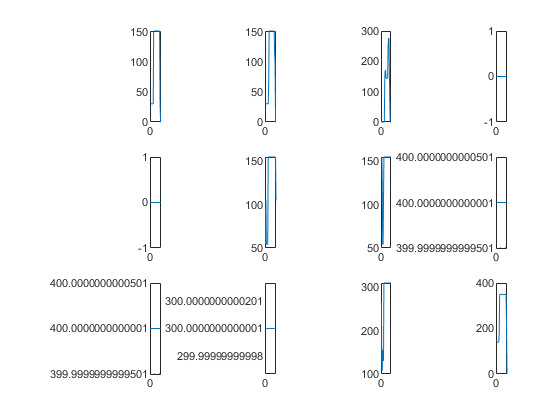

% Plot puissances
for i=1:c
    subplot(3, 4, i)
    plot(1:h, Psol(:, i))
end

function pen = penalityInt(P, intcon)
X = P(intcon);
pen = 1e5*sum(-X.*(X-1));
end


function X = GenerateInitialPoints(nbPoints, Aineq, bineq, Aeq, beq, lb, ub)
% Create individuals on the feasible boundary and then generate some points
% inside the boundary by a convex combination (in LHS sense) of boundary
% points.
while indiv <= popSize
    if directionCounter > maxDirections
        break;
    end
    directionCounter = directionCounter + 1;
    if indiv > 2 % Generate directions from a new point
        % Coefficient for linear combination of directions
        alpha = randperm(indiv-1)./((indiv-1)*(indiv/2)); 
        x = (alpha.*ones(1,(indiv-1))*initialPopulation(1:indiv-1,:))';
    end
    % Get random directons that spans the feasible region
    try
        [Basis, NormalCone] = lcondirections(true,1,x,linCon.Aineq,linCon.bineq,linCon.Aeq,linCon.lb,linCon.ub,tol);
        DirVector = [Basis NormalCone];
    catch % lcondirections will error for degenerate active constraints
        if  directionCounter < maxDirections
            continue;
        else
            break;
        end
    end
    % Total number of search directions
    nDirTotal = size(DirVector,2);
    % Make the index vector to be used to access directions
    indexVec = [1:nDirTotal 1:nDirTotal];
    % Vector to take care of sign of directions
    dirSign = [ones(1,nDirTotal) -ones(1,nDirTotal)];
    OrderVec = 1:length(indexVec);
    % Total number of trial points
    numberOfDirections = length(OrderVec);

    % Inequality constraints at x
    if ~isempty(A)
        constr = A*x-B;
    else
        constr = 0;
    end
    for k = 1:numberOfDirections
        direction = dirSign(k).*DirVector(:,indexVec(OrderVec(k)));
        if ~isempty(A)
            proj_direction = A*direction;
            % Select directions that are not singular
            indf = proj_direction > errnorm*norm(direction);
            if ~any(indf) % No constraints to hit
                maxStep = max(maxStep,1);
            else % Find distance to the nearest constraint
                dist = abs(constr(indf)./proj_direction(indf));
                maxStep =  min(dist);
            end
        else
            maxStep = max(maxStep,1);
        end
        % Reject very close points
        if maxStep <= eps
            continue;
        end
        step = x + direction*maxStep;
        if isTrialFeasible(step,A,B,linCon.Aeq,linCon.beq,[],[],tol)
            initialPopulation(indiv,:) = step';
            indiv = indiv + 1;
        end
        if indiv > popSize + 1
            break;
        end
    end
end % Points on the boundary are generated

% Generate points inside the feasible boundary
if indiv > 1
    initialPopulation(indiv:end,:) = [];
    popSize = size(initialPopulation,1);
    if popSize > 2
        % Get half the population on the boundary and other half inside
        interior_points = ceil(min(npop,popSize)/2);
        boundary_points = min(npop,popSize) - interior_points;
        % Chose individuals with higher distance measure (on the boundary)
        crowdingDistance = distancecrowding(initialPopulation(1:indiv-1,:),[],[],'genotype');
        [unused,index] = sort(crowdingDistance,'descend');
        % Select half points on the boundary; do not overwrite
        % initialPopulation yet (they will be used for interior points)
        tempPopulation = initialPopulation(index(1:boundary_points),:);
        % Generate a convex LHS-type convex combination for the interior points
        if interior_points > 0
            initialPopulation(boundary_points+1:interior_points+boundary_points,:) = ...
                lhsLambda(interior_points,size(tempPopulation,1))*tempPopulation;
            initialPopulation(interior_points+boundary_points+1 :end,:) = [];
        end
        initialPopulation(1:boundary_points,:) = tempPopulation;
        % Make sure the population is feasible (bounds may not be satisfied
        % by 'active-set' algorithm and that may result in infeasible
        % population.
        feasible = isTrialFeasible(initialPopulation,linCon.Aineq,linCon.bineq, ...
                linCon.Aeq,linCon.beq,linCon.lb,linCon.ub,options.TolCon);
        initialPopulation(~feasible,:) = [];
    end
else % Could not generate feasible population
    initialPopulation = [];
end
end